# Gearshift Characterization

This code aims to produce a model that enables the team to do a more precise job of construction and calibration of the gearshift for all the future prototypes.

clc
clear all
close all

## **Data inquiry** 

Here are used two function written by us. 

The first one** (readCond)** simply takes the values of the atmospheric conditions for each run and saves it in separate float values.

The second one** (readRace)** takes all the values of the race mesured by the onboard sensors, in particular each parameter is teken 1 second after the other, so the number of parameters matches the lenght of the race.

%[~,~,~,~,~,m,~,radius,ID] = readCond('');
ID = 'Enzo_15_09_2023_AM';
radius = 0.23157;
m = 80;
[altitude,RPM,dist,vel_lin,power] = readRace(ID);

%[time,vel,power,dist,Hrate] = readRaceCer('cerberus_run_corta_mattina_16');

## Gear Effect

The first 3 values are just initialization to optimize the code, so the vectors are not created in the for cycle.

The for cycle converts the rpm of the pedals (RPM) in rpm of the wheel by passing the cadence to the function gearchange that separates each gear. The filter works by assuming that every drop in cadence is linked to a gear change (actually it's true) and the cycle identifies this drops.

Then it's computed torque by using a common formula of mechanics.

The variables are assigned in the following way:

- Actual velocity --> vel_lin;

- RPM based on actual velocity with gear shift effect --> RPM_bo_vel_lin;

- Input RPM pedal --> RPM;

- Fitted RPM wheel velocity --> RPM_fit;

- RPM of the wheel based on input RPM (pedals) --> RPM_wheel_bo_RPM_pedal;

- Linear velocity of the wheel based on RPM_wheel --> vel_lin_bo_RPM.

[~, RPM_wheel_bo_RPM_pedal, n] = GearChangeDetect(RPM,power,0);

## Fitting to clean the data

[fitresult, gof] = gearFit(dist, RPM_wheel_bo_RPM_pedal);

In case the data from the wheel velocity are to messy, this fitted curve can be used.

fitted = fitresult.a*exp( fitresult.b*dist ) + fitresult.c*exp( fitresult.d*dist );

## Dissipation Factor 

In order to obtain dissipation factor, we need to first find the power generated by the input pedal (RPM) and the power which is consumed in the wheel. To do so, we first need to convert the pedal RPM into the wheel RPM by means of gear shifting, then following up the relationship between linear and angular velocity we can have the linear velocity based on the RPM of the pedal. 

The next step is to calculate $P_i=\frac{\delta J_i}{\delta x_i}$ and $\tilde P_i=\frac{\delta \tilde J_i}{\delta x_i}$, both from the actual and calculated linear velocity. The final step is to find the fraction between the integral of both with respect to the distance, which is reffered to the *Dissipation Factor* $\Lambda=\frac{\int P_i \space\delta x}{\int \tilde P_i \space\delta x}$.

## Results and Plots

vel_lin_bo_RPM is the velocity of the wheel based on the RPM count. 

Line 40 basically takes the RPM of the wheel which is obtained previously and by means of $V=r\dot \theta$ and by multipliing by 3.6 we obtain velocity in terms of Km\h.

vel_lin_bo_RPM = RPM_wheel_bo_RPM_pedal * radius * pi/30 * 3.6 ; 
error = mean(abs( vel_lin - vel_lin_bo_RPM) ./ vel_lin);
fprintf("Error = %4.2f",error)

Error = 0.15

if error < 0.15
    disp("The error is acceptable");
else 
    disp("The error is too high");
end

The error is acceptable


bike =  "phoenix";
[Lambda, cal] = dissFactorCalc(RPM_wheel_bo_RPM_pedal,vel_lin_bo_RPM,bike,radius,m,ID)

Lambda = 0.7639

cal = 1.7840e+04

DevStandPowerReal = std(power)

DevStandPowerReal = 44.5181

meanPower = mean(power)

meanPower = 221.9288

Calculating vel_lin_bo_RPM corrected by the error between vel_lin and vel_lin_bo_RPM

vel_lin_corr = vel_lin_bo_RPM/(1+error); 

A lot of stuffs but it's just to plot the data 

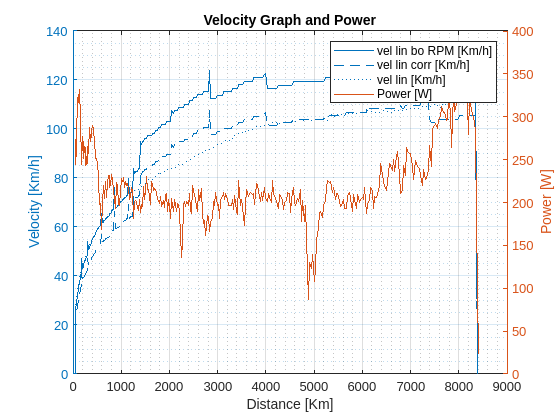

yyaxis left
plot(dist ,vel_lin_bo_RPM, dist, vel_lin_corr,dist, vel_lin);
yyaxis right
plot(dist,power);
legend("vel lin bo RPM [Km/h]", "vel lin corr [Km/h]", "vel lin [Km/h]", "Power [W]");
xlabel("Distance [Km]");
title("Velocity Graph and Power");
grid on 
grid minor
yyaxis right
ylabel("Power [W]")
yyaxis left
ylabel("Velocity [Km/h]")

max_speed_real = max(vel_lin)

max_speed_real = 113.1340

## Building the model

sys = [vel_lin,power];
nx = 1;
model = n4sid(sys,nx)

model =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
           x1
   x1  0.9929
 
  B = 
               u1
   x1  -7.556e-06
 
  C = 
           x1
   y1  -513.6
 
  D = 
       u1
   y1   0
 
  K = 
            y1
   x1  -0.0019
 
Sample time: 1 seconds

Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 4
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using N4SID on time domain data.       
Fit to estimation data: 98.27% (prediction focus)
FPE: 0.1352, MSE: 0.132                          
 


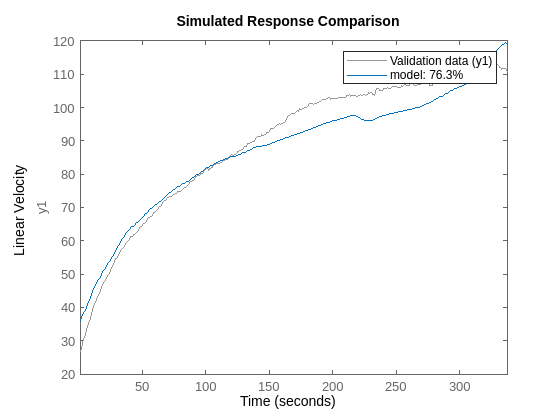

compare(sys,model);
ylabel("Linear Velocity");

## Simulation 

In this section you can simulate the run based on a mean power of your choiche. This part takes in account the oscillating power input by introducing a **Scatter factor **between **a = 85%** and **b = 115%** of the mean power. The scatter factor has beed optimized to match the standard deviation of the power input in real data, so you do not have to modify it. The only case in which is acceptable to modify it, is if the standard deviation in power of a dataset is very different from the one calculated here.

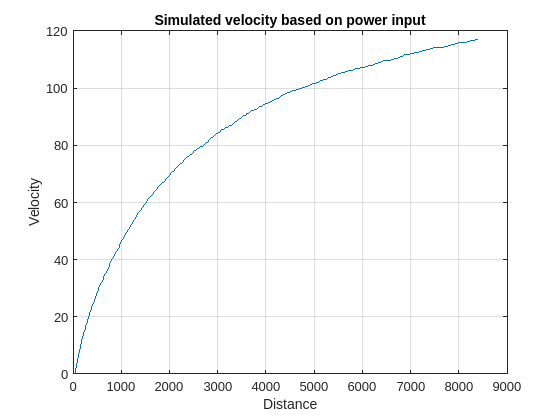

k = size(n,1);

a = 0.829;
b = 1.15;
ScatterFactor = a + (b-a)*rand(k,1);

SimPowerMean =235;

simPower = ScatterFactor*SimPowerMean;
simSpeed = sim(model,simPower);

plot(dist, simSpeed);
title("Simulated velocity based on power input");
xlabel("Distance");
ylabel("Velocity");
grid on;

MaxSimSpeed = max(simSpeed)

MaxSimSpeed = 117.1660